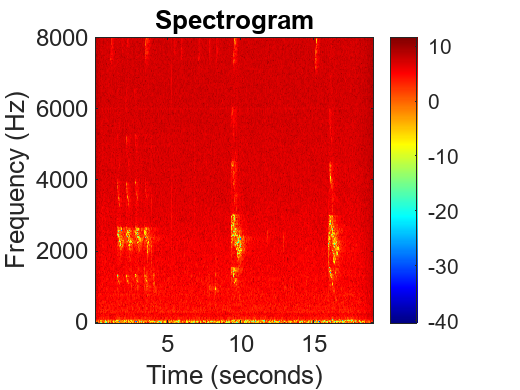

% Load the audio file
[audioData, fs] = audioread('hawk_337669.mp3');
soundsc(audioData,fs);


if size(audioData, 2) == 2
    audioData = mean(audioData, 2);
end

% Downsample to 16 kHz
targetFs = 16000;
if fs ~= targetFs
    audioData = resample(audioData, targetFs, fs);
    fs = targetFs;
end


% Define your window length & step size in terms of number of samples.
winlen = 512;
Step = 256;

% This function converts the x-vector into a matrix where each row is a
% single frame
xf = FrameSignal(audioData,winlen,Step);

nfft = winlen; 

n_frames = size(xf, 1);  
STFT = zeros(nfft, n_frames); 

window = hamming(winlen);

for i = 1:n_frames
    frame = xf(i, :)' .* window;  
    fft_frame = fft(frame, nfft); 
    STFT(:, i) = fft_frame;  
end

[STFT_ref,f,t] = spectrogram(audioData,window,Step,winlen,fs);



% Parameters for STFT
frameLength = 512;
overlapLength = 256;

% Apply STFT with a Hamming window
window = hamming(frameLength, 'periodic');
[S, F, T] = spectrogram(audioData, window, overlapLength, frameLength, fs);



% Normalize spectrogram for better CNN processing
S = abs(S); % Magnitude of the spectrogram
S = log(S + eps); % Log scale to compress dynamic range


% Low-pass filter with cutoff frequency 6250 Hz
lowPassFilter = designfilt('lowpassiir', 'FilterOrder', 8, ...
                           'HalfPowerFrequency', 6250, 'SampleRate', fs);

% Apply the low-pass filter to the spectrogram
S_filtered = filter(lowPassFilter, S);


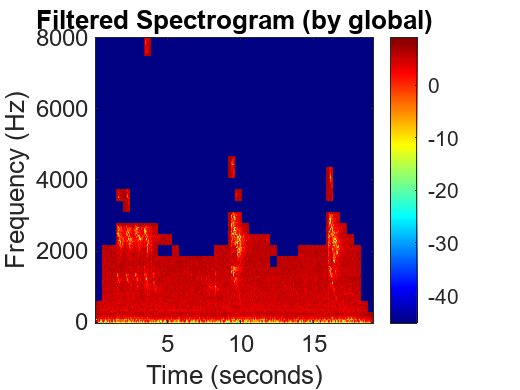


% Get size of the spectrogram
[rows, cols] = size(S_filtered);

% Split the spectrogram into 30x10 cells
timeSteps = 30;
freqSteps = 10;

% Calculate the global mean and variance of the spectrogram
global_mean = mean(S_filtered(:));
global_variance = var(S_filtered(:));

% Threshold based on mean + variance rule
threshold = 1.5 * (global_mean + global_variance);


% Duplicate filtered spectogram
f_spec = S_filtered;


% Loop through each cell (time x frequency) and check the mean
for row = 1:freqSteps:rows
    for col = 1:timeSteps:cols
        % Make sure the cell does not go out of bounds
        row_end = min(row + freqSteps - 1, rows);
        col_end = min(col + timeSteps - 1, cols);

        % Extract the current cell
        cell_data = S_filtered(row:row_end, col:col_end);

        % Calculate the mean of the current cell
        cell_mean = mean(cell_data(:));

        % If the mean of the cell is less than the threshold, toss it
        if cell_mean < threshold
            % Set the cell to zero if it doesn't meet the threshold
            f_spec(row:row_end, col:col_end) = 0;
        end
    end
end
